%% MATLAB线性回归、 广义线性回归 (glmfit函数)
M = csvread('data/confirmes.csv',2,2,[2,2,100,10])

M =           25           7           5          13       15484       13975         321           1           5
          27           0          18           9       15459       13922         320           1           6
          14           3           7           4       15432       13865         319           1           5
          26           7           3          16       15418       13814         317           1           6
          24          11           3          10       15392       13756         317           1           6
          20           5           1          14       15368       13704         317           1           7
          17           5           5           7       15348       13637         316           1           7
          24           1           6          17       15331       13571         316           1           5
          15           2           6           7       15307       13508         315           1           5
          24   

x1 = M(:,2:9);
y = M(:,1);
[b,bint,r,rint,stats] = regress(y,x1,0.05)

b =     0.9944
    0.0118
    1.0027
   -0.0038
    0.0018
    0.1000
    6.8273
   -0.0038


bint =     0.9715    1.0173
   -0.0114    0.0351
    0.9771    1.0283
   -0.0082    0.0007
    0.0004    0.0031
   -0.0705    0.2706
   -3.1467   16.8013
   -0.1008    0.0932


r =    -0.7180
   12.2042
    1.4613
   -2.2592
   -2.2149
   -4.2291
   -0.1131
    0.8717
    1.0267
    2.2009


rint =    -5.2327    3.7968
    8.4849   15.9236
   -3.0809    6.0035
   -6.7977    2.2792
   -6.7615    2.3318
   -8.7110    0.2527
   -4.6993    4.4731
   -3.7249    5.4684
   -3.5846    5.6379
   -2.3998    6.8016


stats = 1.0e+03 *

    0.0010    6.4949    0.0000    0.0056


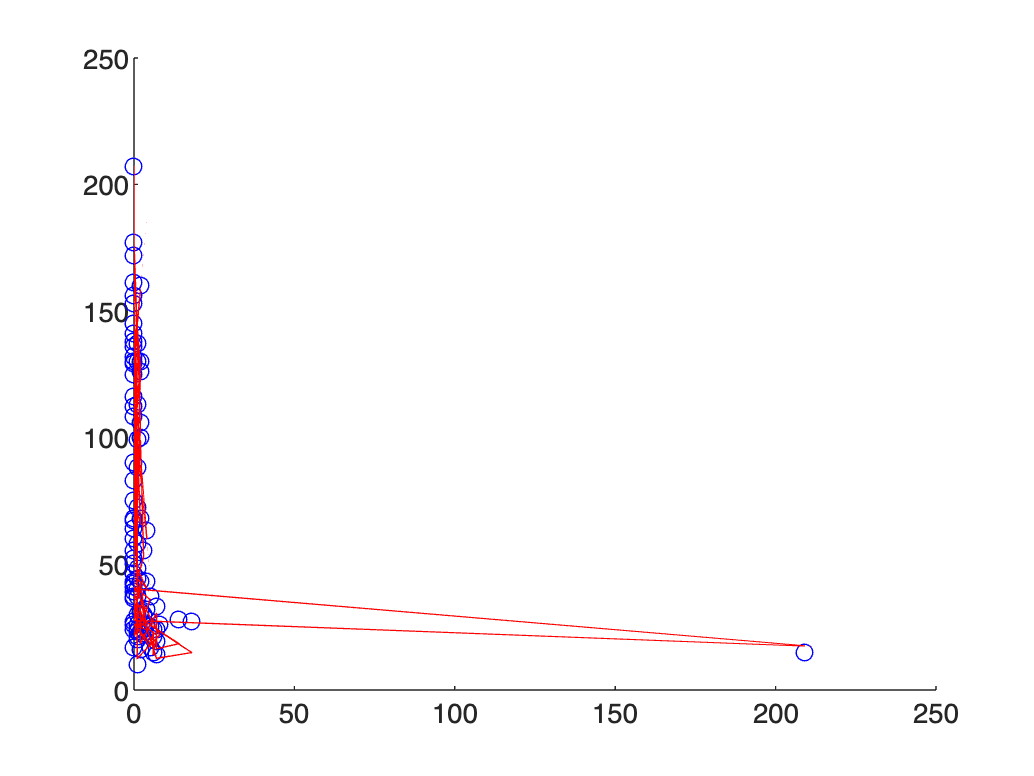

%示意图
yfit= x1*b;
scatter(x1(:,2),y,'blue')  
hold on   
plot(x1(:,2),yfit,'r-')
hold off

%%regress介绍(试错）

%输入值 同上
%函数求解
[b2,bint2,r2,rint2,stats2] = regress(y,x1(:,2),0.05) %会报错"警告: R 方和 F 统计量的定义不良，除非 X 有一列全部为 1。键入 "help regress" 了解详细信息。"

b2 = 0.2159

bint2 =    -0.6054    1.0372


r2 =    23.9205
   23.1137
   12.4887
   25.3523
   23.3523
   19.7841
   15.9205
   22.7046
   13.7046
   22.4887


rint2 =  -150.7320  198.5729
 -150.9587  197.1861
 -162.1653  187.1426
 -149.3232  200.0277
 -151.3345  198.0390
 -154.9362  194.5043
 -158.7690  190.6099
 -151.9330  197.3421
 -160.9711  188.3802
 -152.1247  197.1020


stats2 = 1.0e+03 *

   -0.0020       NaN       NaN    7.6748


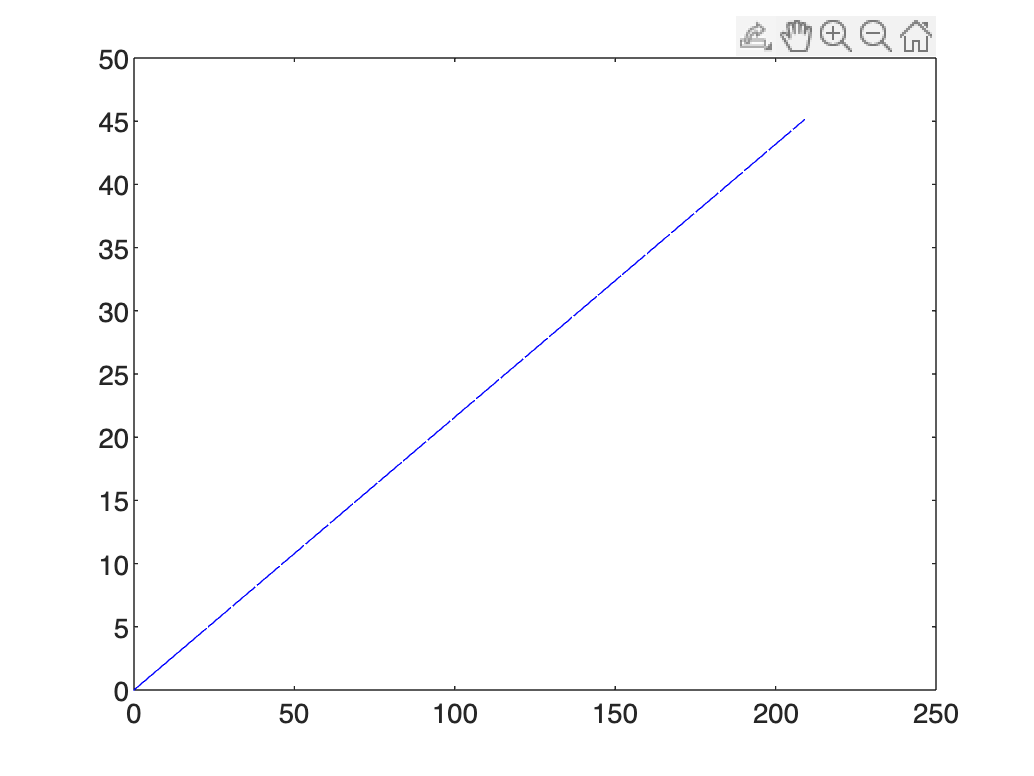

%示意图 必过（0,0）
plot(x1(:,2),x1(:,2)*b2,'b--')
hold off

x1 = M(:,2);    %定义自变量
x2 = M(:,3);    % 定义自变量（含空值）
y = M(:,4);        %定义因变量
X = [ones(size(x1)) x1 x2 x1.*x2];  %很重要 一定要有第一列常数项
b = regress(y,X)    % 回归时空值自动剔除

b =    18.3173
    0.2753
   -0.4709
    0.0419


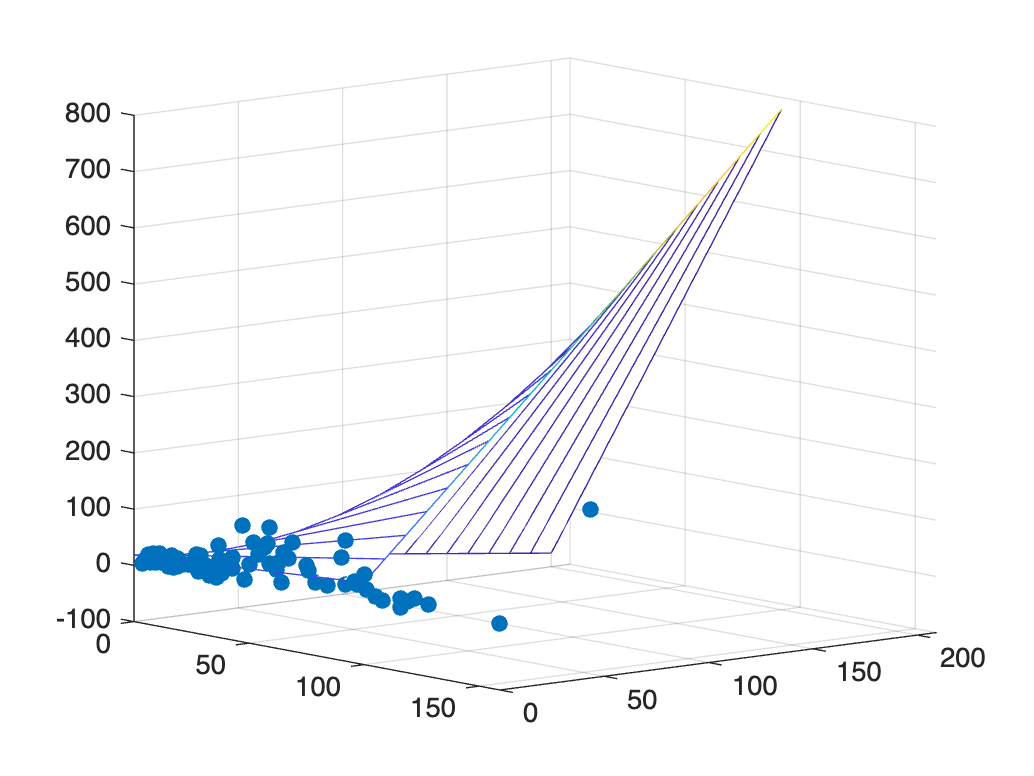

scatter3(x1,x2,y,'filled')   %画出真实值y与自变量的关系
hold on  %保留当前坐标区中的绘图
%%准备画预测值
x1fit = min(x1):100:max(x1); %规定预测值的x1的取值范围
x2fit = min(x2):10:max(x2);  %规定预测值的x2的取值范围（中间数越大，网格越密）
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit); %将x1、x2的新取值范围导入二维网格
YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT; %根据之前算出的模型参数b，计算y的预测值
mesh(X1FIT,X2FIT,YFIT) %画三维坐标图，是预测值y与自变量的关系，三个指标分别对应（X,Y,Z),
view(50,10)  %view(方位角，仰角），更直观地看图
hold off   %不保留作图

%% MATLAB 决策树 (包括分类决策树与回归决策 树 、ID3决策树、C4.5决策树)、随机森林 (MATLAB 有现成的包)
M = csvread('data/confirmes.csv',2,2,[2,2,101,10])

M =           25           7           5          13       15484       13975         321           1           5
          27           0          18           9       15459       13922         320           1           6
          14           3           7           4       15432       13865         319           1           5
          26           7           3          16       15418       13814         317           1           6
          24          11           3          10       15392       13756         317           1           6
          20           5           1          14       15368       13704         317           1           7
          17           5           5           7       15348       13637         316           1           7
          24           1           6          17       15331       13571         316           1           5
          15           2           6           7       15307       13508         315           1           5
          24   

meas = M(:,2:9);
species = M(:,1);

a = randperm(100);
Train = meas(a(1:80),:); 
y_Train = species(a(1:80),:);
Test = meas(a(81:end),:); 
y_Test = species(a(81:end),:);
Tree = fitctree(Train,y_Train);
view(Tree) %文本形式

分类的决策树
 1  if x1<13 then node 2 elseif x1>=13 then node 3 else 26
 2  if x3<8 then node 4 elseif x3>=8 then node 5 else 26
 3  if x1<30 then node 6 elseif x1>=30 then node 7 else 37
 4  class = 15
 5  if x4<15240.5 then node 8 elseif x4>=15240.5 then node 9 else 26
 6  if x4<14860 then node 10 elseif x4>=14860 then node 11 else 37
 7  if x1<110.5 then node 12 elseif x1>=110.5 then node 13 else 130
 8  if x3<17.5 then node 14 elseif x3>=17.5 then node 15 else 26
 9  class = 24
10  if x2<1.5 then node 16 elseif x2>=1.5 then node 17 else 43
11  class = 37
12  if x3<81 then node 18 elseif x3>=81 then node 19 else 130
13  class = 145
14  if x1<4 then node 20 elseif x1>=4 then node 21 else 26
15  class = 27
16  if x2<0.5 then node 22 elseif x2>=0.5 then node 23 else 39
17  class = 43
18  if x1<65.5 then node 24 elseif x1>=65.5 then node 25 else 130
19  class = 172
20  class = 16
21  class = 26
22  class = 39
23  class = 44
24  if x1<36.5 then node 26 elseif x1>=36.5 then node 27 else 42
25  

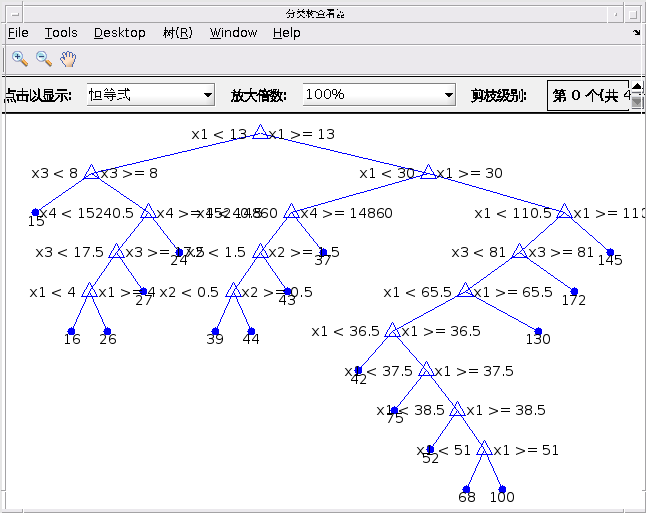

view(Tree,'mode','graph') %图片形式 

%对测试集进行预测
y_pre = predict(Tree,Test);


%未剪枝的重采样误差
resubDefault1 = resubLoss(Tree);
disp(['剪枝前决策树的重采样误差:' num2str(resubDefault1)]);

剪枝前决策树的重采样误差:0.6125



%未剪枝的交叉验证误差
lossDefault1 = kfoldLoss(crossval(Tree));

disp(['剪枝前决策树的交叉验证误差:' num2str(lossDefault1)]);

剪枝前决策树的交叉验证误差:0.9



%% 剪枝
[~,~,~,bestlevel] = cvLoss(Tree,'subtrees','all','treesize','min');

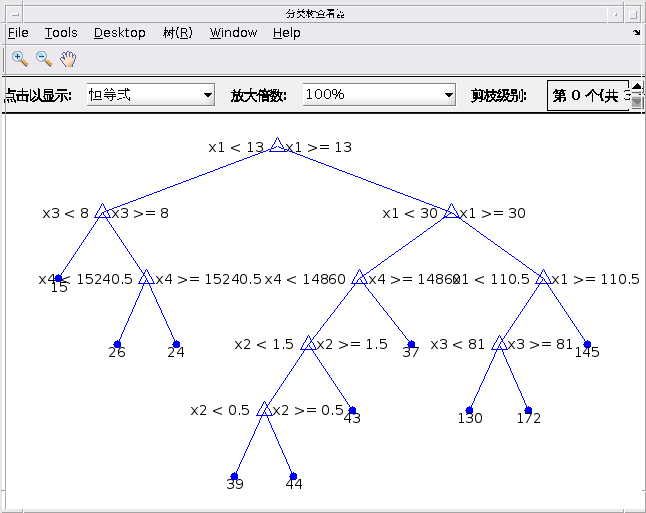

%剪去最低的一层
cptree = prune(Tree, 'Level',1);
%最佳修剪的决策树
bestptree = prune(Tree, 'Level',bestlevel);
view(cptree,'mode','graph')

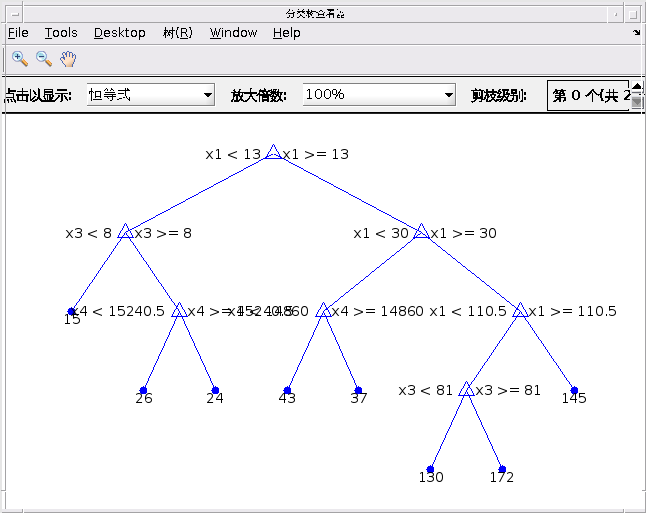

view(bestptree,'mode','graph')


%剪去一层的重采样误差
resubDefault2 = resubLoss(cptree);
disp(['剪去一层后决策树的重采样误差:' num2str(resubDefault2)]);

剪去一层后决策树的重采样误差:0.7
